# 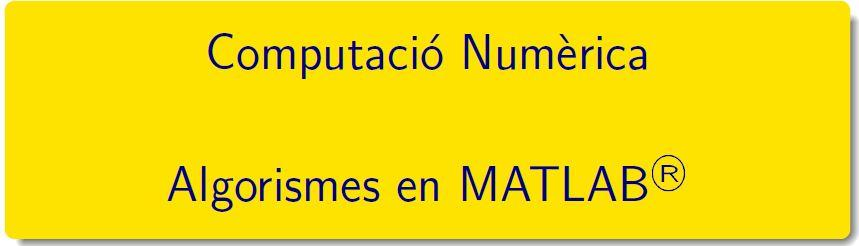

====================================================================================

# Pràctica 2 - Activitat 2: evitar propagació errors

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`

## Algorismes

### Evitar la propagació d'errors

Per tal de reduir o evitar la propagació dels errors es recomana, minimitzar el nombre d’operacions, reordenar les operacions i replantejar el problema en altres termes.

#### Exercici 10, pàgina 21. Equació de segon grau

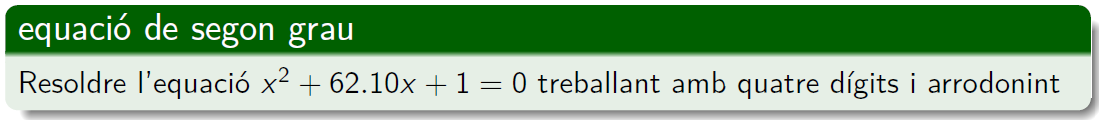

clearvars, format, n = 4;
fprintf('fent ús de roots'), arrels = roots([1,62.10 1])

fent ús de roots

arrels =   -62.0839
   -0.0161


Es calcula amb la fórmula $\frac{-b\pm\sqrt{b^2-4ac}}{2a}=-31.05\pm\sqrt{31.05^2-1}$

aux1 = round((31.05)^2, n, 'significant');
aux2 = round(sqrt((31.05)^2 - 1), n, 'significant');
x1 = round(-31.05 - aux2, n, 'significant')

x1 = -62.0800

x2 = round(-31.05 + aux2, n, 'significant')

x2 = -0.0200

Es calcula amb la fórmula $x_1=-31.05-\sqrt{31.05^2-1},\quad  x_3 = 1/x_1$

x3 = round(1/x1, n, 'significant')

x3 = -0.0161

Xifres decimales correctes

#### Exercici 11, pàgina 21. Equació de segon grauRegla de Horner

Per avaluar expressions polinomials 

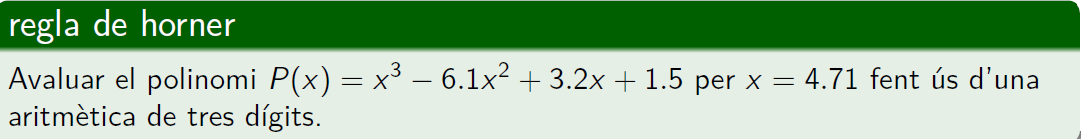

- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$

clearvars   %, format shortG
x = 4.71, n = 3; 

x = 4.7100

coeffs = [1, -6.1, 3.2, 1.5];
valor_exacte = horner(coeffs,x)

valor_exacte = -14.2639

valor_horner_digits = hornerD(coeffs,4.71,n)

valor_horner_digits = -14.3000

xs = abs((valor_horner_digits-valor_exacte)/valor_exacte);

- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$fent ús d'una aritmètica aritmética de tres dígits

Suma ordre creixent potències x

%potències ascendents
pasc = round(1.5, 3, 'significant');
pasc = round(pasc + 3.2.*x, 3, 'significant');
pasc = round(pasc - 6.1.*x.^2, 3, 'significant');
pasc = round(pasc + x.^3, 3, 'significant')

pasc = -14.5000

Suma ordre decreixent potències x

- Error relatiu

function [ pa ] = horner(coeff,a)
%   HORNER avalua el polinomi de grau n
%   p(x) = coeff(1)x.^n + coeff(2)x.^(n-1) + ... + coeff(n-1)x + coeff(n)
%   en x=a pel mètode de horner
pa = coeff(1);
x=a;
for k=2:length(coeff)
    pa = pa.*x + coeff(k);
end
return
end
function [ pa ] = hornerD(coeff,a,d)
%   HORNER avalua el polinomi de grau n
%   p(x) = coeff(1)x.^n + coeff(2)x.^(n-1) + ... + coeff(n-1)x + coeff(n)
%   en x=a pel mètode de horner fent ús de d dígits
pa = coeff(1);
x = a;
for k=2:length(coeff)
    pa = round(pa.*x,d,'significant') + round(coeff(k), d, 'significant');
end
return
end

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`